# Spectrum Analysis of Signals

This example shows downstream spectrum analysis of signals using MATLAB®,  Communications Toolbox™ and DSP System Toolbox™. You can either use captured signals, or receive signals in real time using the RTL-SDR Radio, ADALM-PLUTO Radio or USRP™ Radio. You can change the radio's center frequency to tune the radio to a band where a signal is present. You can then use the spectrum analyzer to view and make measurements on the received spectrum.

For Simulink® implementation of this example, refer [Spectrum Analysis of Signals in Simulink](docid:comm_ug#sdrexample-SpectralAnalysisSimulink).

### Required Hardware and Software

To run this example using captured signals, you need the following software:

[Communications Toolbox](https://www.mathworks.com/products/communications.html)

[DSP System Toolbox](https://in.mathworks.com/products/dsp-system.html)

To receive signals in real time, you also need one of the following hardware:

- RTL-SDR radio and the corresponding software [Communications Toolbox Support Package for RTL-SDR Radio](https://www.mathworks.com/hardware-support/rtl-sdr.html)

- ADALM-PLUTO radio and the corresponding software [Communications Toolbox Support Package for ADALM-PLUTO Radio](https://www.mathworks.com/hardware-support/adalm-pluto-radio.html)

- USRP radio and the corresponding software [Communications Toolbox Support Package for USRP Radio](https://in.mathworks.com/hardware-support/usrp.html) 

For a full list of Communications Toolbox supported SDR platforms, refer to the "MATLAB and Simulink Hardware Support for SDR" section of [Software-Defined Radio (SDR)](https://www.mathworks.com/discovery/sdr.html).

### Example Code

The receiver asks for user input and initializes variables. Then, it calls the signal source and FM broadcast receiver in a loop. The loop also keeps track of the radio time using the frame duration and lost samples reported by the signal source.

For the option to change default settings, set |cmdlineInput| to 1.

cmdlineInput = false;
if cmdlineInput
%     Request user input from the command-line for application parameters
    userInput = helperSpectralAnalysisUserInput;
%     Set initial parameters
    [SAParams, sigSrc] = helperSpectralAnalysisConfig(userInput);
else
%     Set initial parameters
    load defaultInputSpecAnalysis.mat
    [SAParams, sigSrc] = helperSpectralAnalysisConfig;
end

## Setup

Create `spectrumAnalyzer` object and configure based on user input

hSpectrum = spectrumAnalyzer(...
    'Name',             'Passband Spectrum',...
    'Title',            'Passband Spectrum', ...
    'Method',           'Welch', ...
    'SpectrumType',     'Power density', ...
    'FrequencySpan',    'Full', ...
    'SampleRate',       SAParams.FrontEndSampleRate, ...
    'SpectralAverages', 50, ...
    'FrequencyOffset',  SAParams.CenterFrequency, ...
    'YLimits',          [-120 10], ...
    'YLabel',           'Magnitude-squared, dB', ...
    'Position',         figposition([50 30 30 40]));

## Stream processing

View the spectrum. While the spectrum analyzer is running, you can measure peaks, occupied bandwidth, and other properties of the signal.

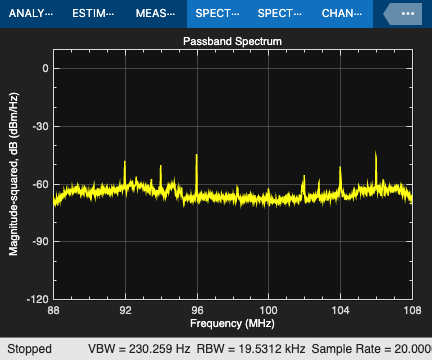

% Initialize radio time
radioTime = 0;

% Main loop
while radioTime < userInput.Duration
  % Receive baseband samples (Signal Source)
  if SAParams.isSourceRadio
      if SAParams.isSourcePlutoSDR
          rcv = sigSrc();
          lost = 0;
          late = 1;
      elseif SAParams.isSourceUsrpRadio
          rcv= sigSrc();
          lost = 0;
      else
          [rcv,~,lost,late] = sigSrc();
      end
  else
    rcv = sigSrc();
    lost = 0;
    late = 1;
  end
  
    rcv = rcv - mean(rcv);  % Remove DC component.
    step(hSpectrum, rcv);

  % Update radio time. If there were lost samples, add those too.
  radioTime = radioTime + SAParams.FrontEndFrameTime + ...
    double(lost)/SAParams.FrontEndSampleRate;
end

% Release all System objects
release(sigSrc);
release(hSpectrum);

## Conclusion

In this example, you used Communications Toolbox™ System objects to analyze the spectrum of a received signal.

*Copyright 2013-2022 The MathWorks, Inc.*